# Laboratorio: optimización sin restricciones

**Autores (Grupo 4):** Javier Blanco Álvarez, Pablo Castañeda Fuentes, Lucía Royo Pascual, Ferrán Soto Moscardó, Jesús Gallinal Moreno.

**Asignatura: **Optimización

## RESUMEN

En esta práctica se examina la aplicación de métodos de optimización del descenso de gradiente para determinar superficies mínimas de revolución, comparando enfoques de pasos fijos y variables. Se implementaron métodos de Fibonacci y Búsqueda dicotómica para la optimización de pasos, analizando su efectividad para encontrar soluciones óptimas. Partiendo de dos funciones iniciales (una línea recta y una parábola), examinamos el comportamiento de convergencia y la precisión de la solución en diferentes niveles de discretización. Con esta práctica se demuestra la implementación práctica de técnicas de optimización multivariable sin restricciones al tiempo que enfatiza la importancia de la selección adecuada de pasos en problemas de optimización. Los resultados indican la efectividad de los métodos de paso variable para lograr mejores características de convergencia en comparación con los enfoques de paso fijo. 

**Palabras clave:** Optimización sin restricciones, descenso del gradiente, método del trapecio, superficies de revolución, Fibonacci, bñusqueda dicotómica. 

## INTRODUCCIÓN

El estudio de superficies mínimas de revolución mediante la optimización del descenso de gradientes representa una combinación útil y rigurosa entre el cálculo de variaciones y los métodos numéricos. En esta práctica se explora la implementación del descenso de gradiente con tasas de aprendizaje fijas y variables para encontrar la superficie de revolución óptima que minimice el área. El análisis abarca dos condiciones iniciales: una línea recta u(x) = 1 y una parábola u(x) = x²-x+1, logrando una comparación integral de los comportamientos de convergencia. El tamaño de paso variable, determinado por Fibonacci y métodos dicotómicos, busca mantener un enfoque adaptativo para la optimización, mejorando potencialmente las tasas de convergencia y la precisión de la solución. En esta práctica examinamos sistemáticamente la relación entre el número de puntos de discretización (N) y la precisión de la solución final obtenida al tiempo que se incluye un estudio detallado de los perfiles de gradiente bajo tamaños de paso fijos y variables, proporcionando información sobre la dinámica de optimización. y características de convergencia.

## Descripción del laboratorio

### **Objetivos**

La idea de este Laboratorio es estudiar un caso de optimización sin restricciones multivariables. Justamente, con la implementación del método del gradiente, se espera aproximar una curva que verifica ciertas condiciones. Esta actividad busca fomentar la exploración, comprensión e implementación del método del descenso del gradiente en un problema exigente desde el punto de vista computacional. Así, se espera que se logre determinar la conexión de este método con lo estudiado para la Actividad 1.

### **Planteamiento del Problema**

El objetivo para esta entrega consiste en encontrar la curva que une los puntos $\left(0,\ 1\right)$ y $\left(1,\ 1\right)$, de forma que se minimice el área de la superficie de revolución alrededor del eje. Para ello, se quiere minimizar la integral:


$$I{\left(u\right)}=\int_0^1 u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }\ dx$$


Sujeta a las condiciones:  $u{\left(0\right)}=1=u\left(1\right)$                   

En realidad, el área deseada es $2\pi I\left(u\right)$. Sin embargo, el factor $2\pi$ no es relevante y se puede normalizar para facilitar los cálculos.

### **Metodología**

Para resolver este problema, realizaremos una discretización del intervalo $\left\lbrack 0,\ 1\right\rbrack$, de forma que tomaremos   intervalos de la forma: ${\left[\frac{j}{n},\ \frac{j+1}{n}\right]}$, para  $0\le j\le n-1$.

 Recordemos que si consideramos una función $f\left(x\right)$, la integración por trapecios nos da la fórmula:

 
$$\int_0^1 f{\left(x\right)}dx\approx \sum_{j=0}^{n-1} \frac{f{\left(x_j \right)}+f\left(x_{j+1} \right)}{2}\cdot \frac{1}{n}=\sum_{j=0}^{n-1} T_j \left(f\left(x\right)\right)$$


En nuestro caso, tendremos $f\left(x\right)\ =u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }$ y llamaremos $u_j \ =\ u\left(x_j \right)$. Como estamos aproximando   por una poligonal, podemos considerar que:


$$u^{\prime } {\left(x_j \right)}\approx \frac{u{\left(x_{j+1} \right)}-u{\left(x_j \right)}}{\frac{1}{n}}=n*\left\lbrack u{\left(x_{j+1} \right)}-u\left(x_j \right)\right\rbrack$$


Es decir, aproximamos la derivada por la derecha para el punto inicial y por la izquierda en el punto final. Por lo que la aproximación de la integral será:

Así pues, se obtiene la siguiente función, que podemos optimizar usando el método del gradiente:

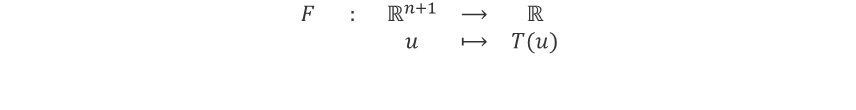

### **Implementación**

Para la implementación, se deben seguir los siguientes pasos:

- Calcular el gradiente de  F                             

- Calcular la curva óptima para los distintos valores de $n$, teniendo en cuenta que:


$$T_j {\left(u\right)}=\frac{1}{2\left(n+1\right)}\cdot {\left(u_{j+1} +u_j \right)}\sqrt{1+{\left(n+1\right)}^2 {{\left(u_{j+1} -u_j \right)}}^2 }$$


- El gradiente está formado por:


$$\nabla F{\left(u_0 ,u_1 ,\ldots,\ u_n \right)}={{\left[g_0 ,g_1 ,\ldots,g_n \right]}}^T$$


Donde:

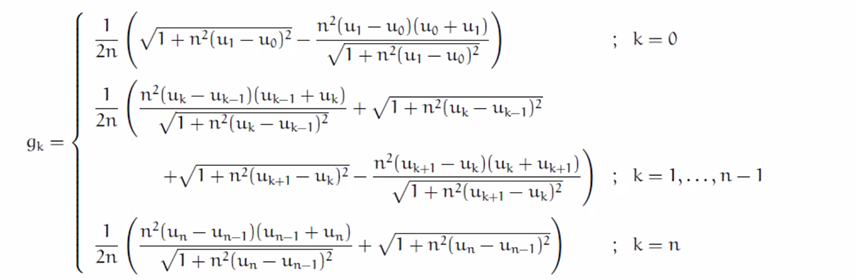

**Pautas de elaboración**

- Deberás determinar cuál es la curva tal que, al considerar su sólido de revolución, el área de superficie es mínima. Para hacerlo, ten en cuenta que la incógnita del problema es una función (es necesario discretizarla, como se explica en los apartados anteriores). Al discretizar, el problema se convierte en uno multidimensional de dimensión alta.

- El informe debe entregarse en formato PDF, donde sea posible discriminar cada uno de los aspectos listados en la tabla anexa para la rúbrica.

- Deberás entregar un fichero en `Matlab` que permita verificar los resultados. Es importante destacar que ese fichero debe correr directamente sin señalar error alguno

## Solución Exacta

clear all; close all;

% Valores iniciales asumidos
a0 = 1;
b0 = 0;

% Definimos sistema de ecuaciones para hacer una resolución numérica (más eficiente) 
fun = @(x) [x(1)*cosh(-x(2)/x(1)) - 1;
            x(1)*cosh((1-x(2))/x(1)) - 1];

% Usamos fsolve para solución numérica
options = optimoptions('fsolve', 'Display', 'off');
sol = fsolve(fun, [a0; b0], options);

% Soluciones de a y b
a_val = sol(1);
b_val = sol(2);
fprintf('a = %f\nb = %f\n', a_val, b_val);

a = 0.848338
b = 0.500000


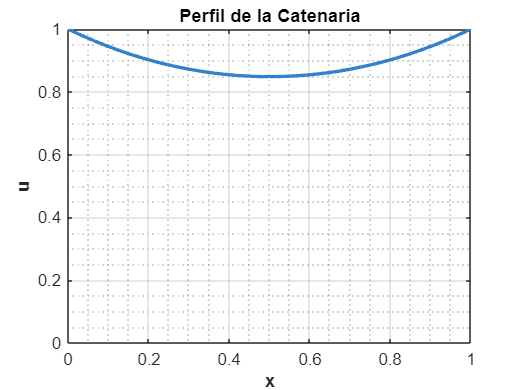


% Función para graficar
u_func = @(x) a_val * cosh((x - b_val)/a_val);

% 2D Plot
figure(1)
x_range = 0:0.01:1;
plot(x_range, u_func(x_range), 'LineWidth', 2, 'Color', [0.2 0.5 0.8])
grid on
xlabel('x', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('u', 'FontSize', 12, 'FontWeight', 'bold')
title('Perfil de la Catenaria', 'FontSize', 14, 'FontWeight', 'bold')
axis([0 1 0 max(u_func(x_range))])
set(gca, 'FontSize', 10)
box on
grid minor

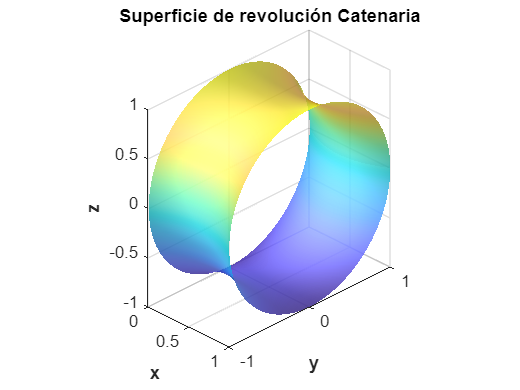


% 3D Plot Superficie de revolución
figure(2)
[X, THETA] = meshgrid(x_range, 0:pi/50:2*pi);
R = u_func(X);
Y = R .* cos(THETA);
Z = R .* sin(THETA);

surf(X, Y, Z, 'EdgeColor', 'none', 'FaceAlpha', 0.8)
xlabel('x', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('y', 'FontSize', 12, 'FontWeight', 'bold')
zlabel('z', 'FontSize', 12, 'FontWeight', 'bold')
title('Superficie de revolución Catenaria', 'FontSize', 14, 'FontWeight', 'bold')
axis equal
colormap('parula')  % Parula para mejor contraste
shading interp
lighting gouraud
camlight('headlight')
material([0.7 0.5 0.3 1]) 
grid on
set(gca, 'FontSize', 10)
view(45, 30) 


% Calculo del área
% Derivada de u
du_dx = @(x) a_val * sinh((x - b_val)/a_val) * (1/a_val);
% Integrando de la función
integrando = @(x) 2*pi * u_func(x) .* sqrt(1 + du_dx(x).^2);
% Integración numérica
A = integral(integrando, 0, 1);

fprintf('Area de Revolución Exacta = %f\n', A);

Area de Revolución Exacta = 5.991797


## **Método de paso fijo**

### **Partiendo de recta u(x)  = 1**

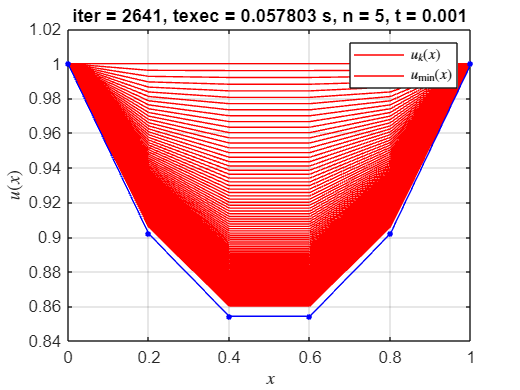

*Solución óptima encontrada en la iteración 2641, para n = 5, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    2638    0.955626522738047    1.00272364775583e-05     0.730368462705179 
    2639    0.955626422252063    1.00153713191927e-05     0.730387682354737 
    2640    0.955626322003745    1.00035205838827e-05      0.73040687906178 
    2641    0.955626221992524    9.99168425298791e-06     0.730426052854624 



Valor mínimo de F(u) = F_min_aprox = 0.955626
|F_min_aprox - I_min_exacta| = 0.002002



*Solución óptima encontrada en la iteración 461, para n = 5, t = 0.010000



     k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ___    _________________    ____________________    ___________________

    458    0.955584097673837    1.02413328827885e-05     0.745090974855061 
    459    0.955584087245861    1.01231594532156e-05     0.745110234093893 
    460    0.955584077057147    1.00063535458431e-05     0.745129270880659 
    461      0.9555840671022    9.89089924541878e-06     0.745148087794666 



Valor mínimo de F(u) = F_min_aprox = 0.955584
|F_min_aprox - I_min_exacta| = 0.001960



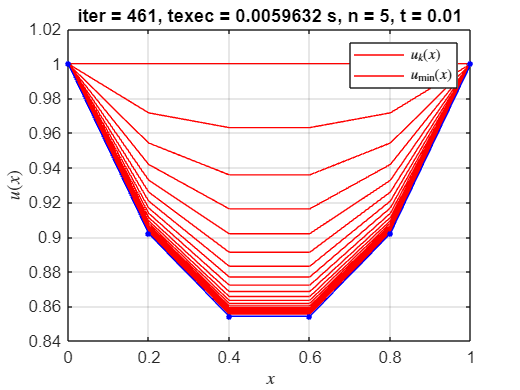

*Solución óptima encontrada en la iteración 43, para n = 5, t = 0.150000



    k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    __    _________________    ____________________    ___________________

    40    0.955583648707284    1.75629487232882e-05     0.746601625392338 
    41    0.955583646828401    1.45310502991858e-05     0.746629244082111 
    42    0.955583645542223    1.20226831291745e-05     0.746652094828346 
    43    0.955583644661759    9.94740466308303e-06     0.746671000972261 



Valor mínimo de F(u) = F_min_aprox = 0.955584
|F_min_aprox - I_min_exacta| = 0.001959



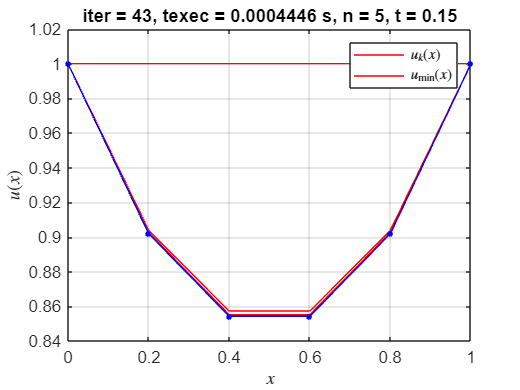

*Solución óptima encontrada en la iteración 4660, para n = 10, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    4657    0.954198901405223    1.00162670725477e-05     0.724480347379062 
    4658    0.954198801109982    1.00102040923685e-05     0.724494598743755 
    4659    0.954198700936122    1.00041449223905e-05     0.724508841321767 
    4660    0.954198600883496    9.99808956012424e-06     0.724523075118804 



Valor mínimo de F(u) = F_min_aprox = 0.954199
|F_min_aprox - I_min_exacta| = 0.000574



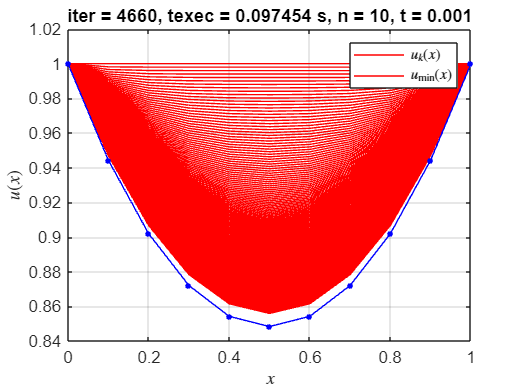

*Solución óptima encontrada en la iteración 854, para n = 10, t = 0.010000



     k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ___    _________________    ____________________    ___________________

    851    0.954115829630747    1.01686421001337e-05     0.745835988394174 
    852    0.954115819320819    1.01092431141167e-05     0.745850127269322 
    853    0.954115809130987    1.00501925344316e-05     0.745864183382601 
    854     0.95411579905985    9.99148830077652e-06     0.745878157221437 



Valor mínimo de F(u) = F_min_aprox = 0.954116
|F_min_aprox - I_min_exacta| = 0.000492



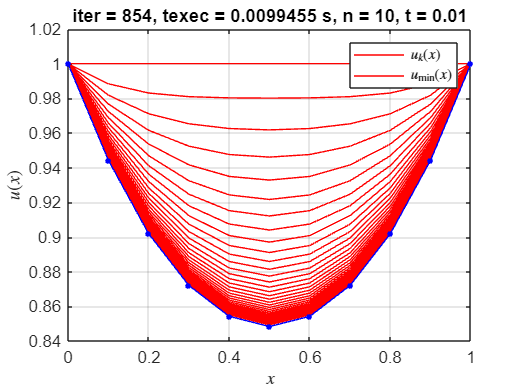

*Solución óptima encontrada en la iteración 10000, para n = 10, t = 0.150000



      k            F(u)          ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ________________    _________________    ___________________

     9997    1.12904143822076    0.258179589445983     2.06033133545535  
     9998    1.14287899353169    0.258179589445983     1.98910249814077  
     9999    1.12904143822076    0.258179589445983     2.06033133545535  
    10000    1.14287899353169    0.258179589445983     1.98910249814077  



Valor mínimo de F(u) = F_min_aprox = 1.129041
|F_min_aprox - I_min_exacta| = 0.175417



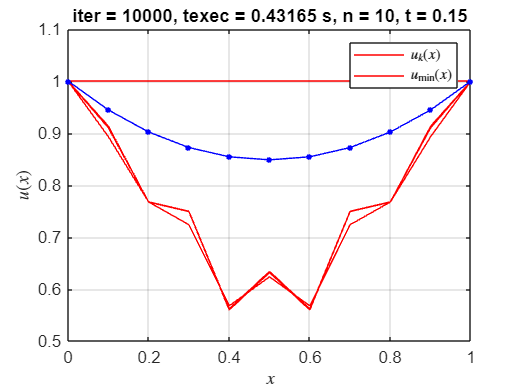

*Solución óptima encontrada en la iteración 6480, para n = 15, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    6477    0.953967127460957    1.00104140776443e-05     0.719314890241955 
    6478    0.953967027273005    1.00063308805193e-05     0.719326681936119 
    6479    0.953966927166767    1.00022494255731e-05     0.719338468701134 
    6480    0.953966827142177    9.99816971214557e-06     0.719350250539196 



Valor mínimo de F(u) = F_min_aprox = 0.953967
|F_min_aprox - I_min_exacta| = 0.000343



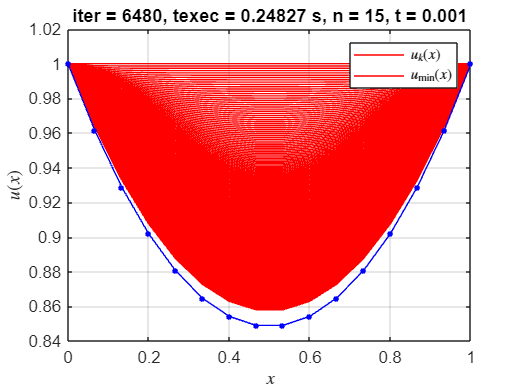

*Solución óptima encontrada en la iteración 1228, para n = 15, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1225    0.953843642657957    1.00978897603945e-05     0.745571830531366 
    1226    0.953843632481134    1.00584463461272e-05     0.745583405455142 
    1227    0.953843622383659    1.00191577789337e-05     0.745594935040469 
    1228    0.953843612364911    9.98002344482953e-06      0.74560641946631 



Valor mínimo de F(u) = F_min_aprox = 0.953844
|F_min_aprox - I_min_exacta| = 0.000219



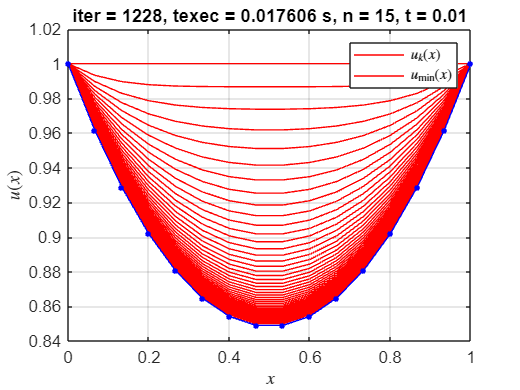

*Solución óptima encontrada en la iteración 10000, para n = 15, t = 0.150000



      k            F(u)          ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ________________    _________________    ___________________

     9997    1.11848525255849    0.177995899920808     1.81360763357685  
     9998    1.11759631706904    0.188284865446705     1.81349540781208  
     9999    1.12861342365255    0.188327170099119     1.76496093123722  
    10000    1.11571159795852    0.177685491931081     1.69472192681556  



Valor mínimo de F(u) = F_min_aprox = 1.115066
|F_min_aprox - I_min_exacta| = 0.161442



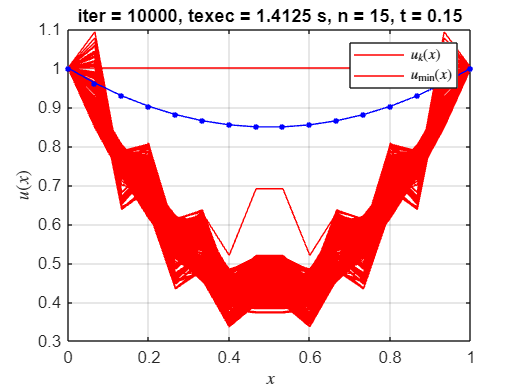

*Solución óptima encontrada en la iteración 8167, para n = 20, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    8164    0.953912270850164    1.00084023782208e-05     0.714870940009798 
    8165    0.953912170697489    1.00053164235918e-05     0.714881229977036 
    8166    0.953912070606565    1.00022314702868e-05     0.714891516677354 
    8167    0.953911970577354    9.99914751814148e-06     0.714901800111869 



Valor mínimo de F(u) = F_min_aprox = 0.953912
|F_min_aprox - I_min_exacta| = 0.000288



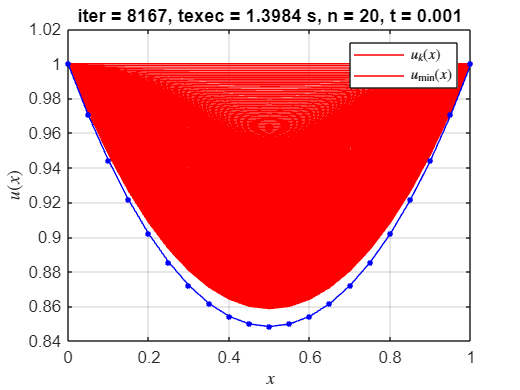

*Solución óptima encontrada en la iteración 1588, para n = 20, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1585    0.953748605378644    1.00645690299098e-05      0.74521343043422 
    1586     0.95374859526395    1.00350393029291e-05     0.745223461377235 
    1587    0.953748585208521    1.00055967200395e-05     0.745233462790861 
    1588    0.953748575212011    9.97624102127733e-06     0.745243434762815 



Valor mínimo de F(u) = F_min_aprox = 0.953749
|F_min_aprox - I_min_exacta| = 0.000124



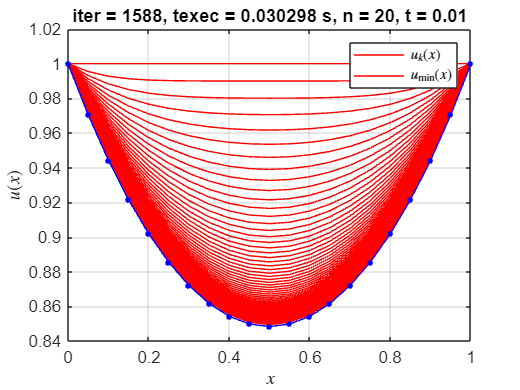

*Solución óptima encontrada en la iteración 10000, para n = 20, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.152079992293084     1.36826208292915  
     9998    -Inf    0.152079992293084     1.51607440516857  
     9999    -Inf    0.152079992293084     1.36826208292915  
    10000    -Inf    0.152079992293084     1.51607440516857  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



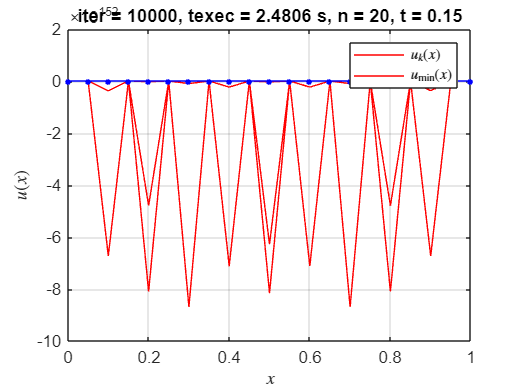

*Solución óptima encontrada en la iteración 9756, para n = 25, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    9753    0.953908372566329    1.00056167223021e-05     0.710943523548078 
    9754    0.953908272466391     1.0003132517474e-05     0.710952776735386 
    9755    0.953908172416152    1.00006489652488e-05     0.710962027547844 
    9756    0.953908072415588    9.99816606530498e-06     0.710971275986107 



Valor mínimo de F(u) = F_min_aprox = 0.953908
|F_min_aprox - I_min_exacta| = 0.000284



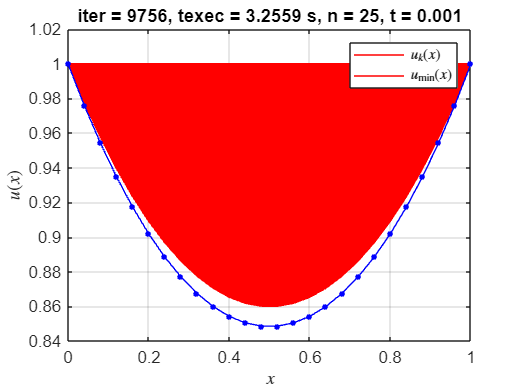

*Solución óptima encontrada en la iteración 1937, para n = 25, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1934    0.953704839956438    1.00556821657521e-05     0.744853310441506 
    1935    0.953704829856643    1.00320548728349e-05     0.744862294234151 
    1936    0.953704819804254    1.00084834559864e-05     0.744871256837296 
    1937    0.953704809799047     9.9849677812648e-06     0.744880198301431 



Valor mínimo de F(u) = F_min_aprox = 0.953705
|F_min_aprox - I_min_exacta| = 0.000081



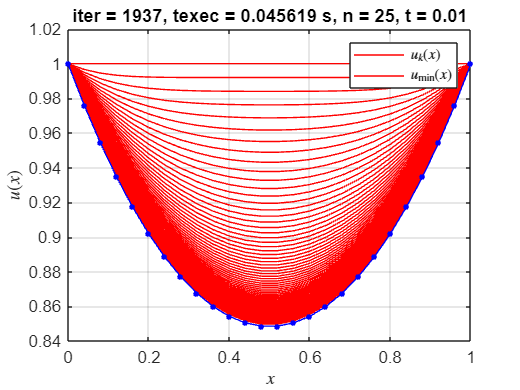

*Solución óptima encontrada en la iteración 10000, para n = 25, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.170947455651523     1.55189195043942  
     9998    -Inf    0.170947455651523      1.6985605131146  
     9999    -Inf    0.170947455651523     1.55189195043942  
    10000    -Inf    0.170947455651523      1.6985605131146  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



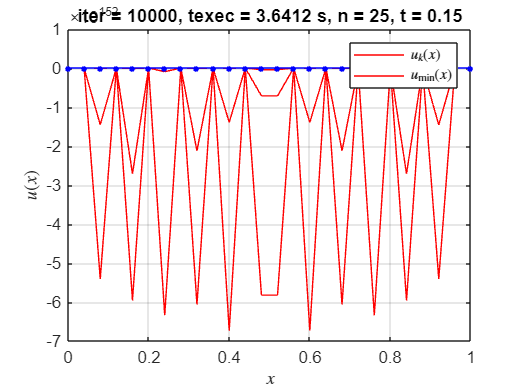

*Solución óptima encontrada en la iteración 10000, para n = 50, t = 0.001000



      k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    _____    _________________    ____________________    ___________________

     9997     0.95590701592008    2.45283423633017e-05     0.620993828914641 
     9998    0.955906414322832    2.45248908709687e-05     0.621011196827833 
     9999    0.955905812894876    2.45214399386799e-05     0.621028562076154 
    10000    0.955905211636164    2.45179895663597e-05     0.621045924660082 



Valor mínimo de F(u) = F_min_aprox = 0.955905
|F_min_aprox - I_min_exacta| = 0.002280



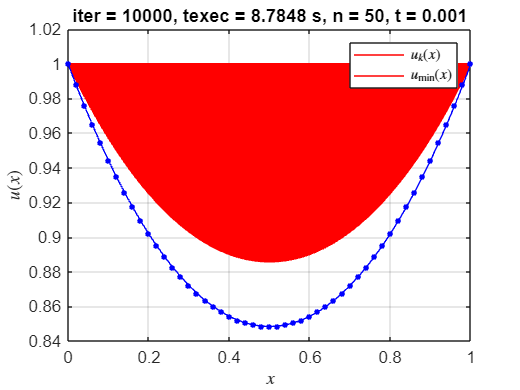

*Solución óptima encontrada en la iteración 3579, para n = 50, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    3576    0.953648032738506    1.00289305314951e-05     0.743332713489656 
    3577    0.953648022686488    1.00171113285069e-05     0.743339077778477 
    3578    0.953648012658148    1.00053061815737e-05     0.743345434524547 
    3579    0.953648002653432    9.99351507376945e-06     0.743351783736934 



Valor mínimo de F(u) = F_min_aprox = 0.953648
|F_min_aprox - I_min_exacta| = 0.000024



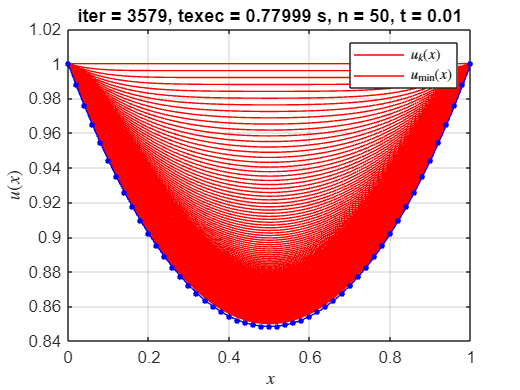

*Solución óptima encontrada en la iteración 10000, para n = 50, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.186786338656144     1.86587795664023  
     9998    -Inf    0.186786338656144     1.72370729187847  
     9999    -Inf    0.186786338656144     1.86587795664023  
    10000    -Inf    0.186786338656144     1.72370729187847  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



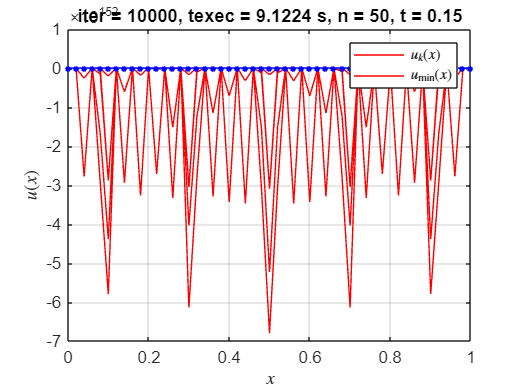

clc; clear; close all;
format longg;
% % parámetros...
n_vector = [5, 10, 15, 20, 25, 50];
t_vector = [0.001, 0.01,0.15];


delta_1 = 1e-5;
delta_2 = 0.75;
max_k = 10000;

% Estructura para guardar resultados
resultados = struct();

% % Crear carpeta para guardar resultados
output_folder = 'resultados_pdf';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

% % salidas...
l = length(n_vector);
tiledlayout(1, l);
iter=0;
tic
for n_idx = 1:length(n_vector)
    for t_idx = 1:length(t_vector)
        % Definir parámetros actuales
        n = n_vector(n_idx);
        t = t_vector(t_idx);    
        iter=iter+1;
        [tabla_iteraciones, u_min_aprox, u_hist, k, texec] = metodo_gradiente_paso_fijo(n, t, delta_1, delta_2, max_k);
        % calculo valores exactos...
        x = 0:1/n:1;
        a = 0.848338;
        u_min_exacta = a*cosh((x-1/2)/a); % catenaria exacta
        I_min_exacta = (a/2)*(1 + a*sinh(1/a)); % se ha obviado el 2*pi
        fprintf('*Solución óptima encontrada en la iteración %d, para n = %d, t = %f\n\n', k, n, t);
        % tabulo...
        disp(array2table(tabla_iteraciones(end-3:end,:), 'VariableNames', {'k', 'F(u)', '||u_{k+1} - u_k||', '||grad_F(u_{k+1})||'}));
        F_min_aprox = F(u_min_aprox);
        
        % Guardar resultados en la estructura
        resultados(iter).n = n;
        resultados(iter).t = t;
        resultados(iter).tabla_iteraciones = tabla_iteraciones;
        resultados(iter).u_min_aprox = u_min_aprox;
        resultados(iter).u_hist = u_hist;
        resultados(iter).k = k;
        resultados(iter).texec = texec;
        resultados(iter).u_min_exacta = u_min_exacta;
        resultados(iter).I_min_exacta = I_min_exacta;
        resultados(iter).F_min_aprox = F_min_aprox;
        resultados(iter).error = abs(F_min_aprox - I_min_exacta);

        fprintf('Valor mínimo de F(u) = F_min_aprox = %f\n|F_min_aprox - I_min_exacta| = %f\n\n', F_min_aprox, abs(F_min_aprox - I_min_exacta));
        % grafico...
        figure(iter);
        plot(x, u_hist(1:20:end,:)', 'r', ...          % Color rojo para u_hist
             x, u_min_aprox', 'r', ...                % Color rojo para u_min_aprox
             x, u_min_exacta, '.-b', 'MarkerSize', 10); % Color azul para u_min_exacta con estilo y tamaño del marcador      
        xlabel('$$x$$', 'Interpreter', 'latex'); 
        ylabel('$$u(x)$$', 'Interpreter', 'latex');
        legend('$$u_{k}(x)$$', '$$u_{\min}(x)$$', 'Interpreter', 'latex');
        title(['iter = ', num2str(k), ', texec = ', num2str(texec), ' s, n = ', num2str(n), ', t = ', num2str(t)]);
        grid on;

        % Guardar la figura
        % saveas(gcf, fullfile(output_folder, sprintf('final_n%d_t%.3f.pdf', n, t)));       
    end
end


elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 9.4489 segundos en ejecutarse.


save('resultados_t_fijo.mat','resultados');

### Partiendo de parábola u(x) = x^2-x+1;

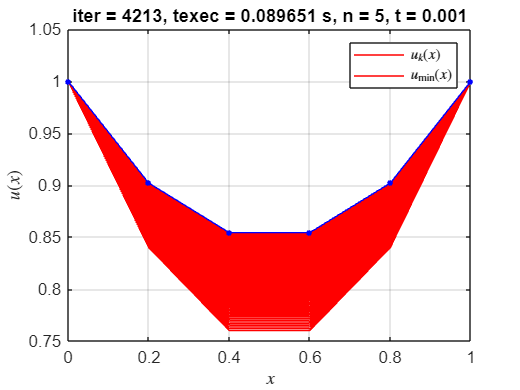

* Parabola:  Solución óptima encontrada en la iteración 4213, para n = 5, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    4210    0.955585326583892    1.96465742220092e-06     0.750009077119862 
    4211    0.955585322726221    1.96240988811541e-06     0.750005355421149 
    4212    0.955585318877371    1.96016491048943e-06     0.750001637970934 
    4213    0.955585315037322    1.95792248645072e-06     0.749997924764405 



Valor mínimo de F(u) = F_min_aprox = 0.955585
|F_min_aprox - I_min_exacta| = 0.001961



* Parabola:  Solución óptima encontrada en la iteración 479, para n = 5, t = 0.010000



     k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ___    _________________    ____________________    ___________________

    476    0.955584104989456    1.03029861030462e-05     0.748445585060375 
    477    0.955584094435187    1.01847993907761e-05     0.748426249831057 
    478     0.95558408412167    1.00679644300026e-05     0.748407136167501 
    479    0.955584074043421    9.95246585109498e-06     0.748388241540872 



Valor mínimo de F(u) = F_min_aprox = 0.955584
|F_min_aprox - I_min_exacta| = 0.001960



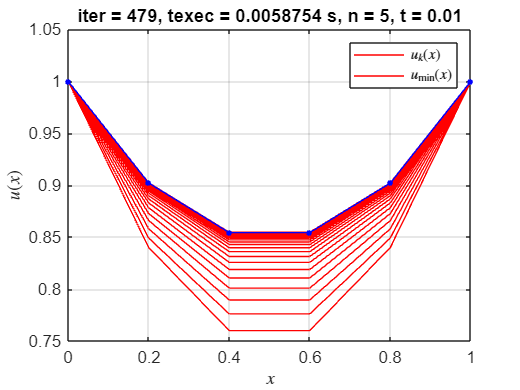

* Parabola:  Solución óptima encontrada en la iteración 45, para n = 5, t = 0.150000



    k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    __    _________________    ____________________    ___________________

    42    0.955583648310193    1.69636837514454e-05     0.746916227324254 
    43    0.955583646557238    1.40370119183676e-05     0.746889552574978 
    44    0.955583645356972    1.16151417047391e-05     0.746867479796112 
    45    0.955583644535154    9.61104260942306e-06     0.746849215259983 



Valor mínimo de F(u) = F_min_aprox = 0.955584
|F_min_aprox - I_min_exacta| = 0.001959



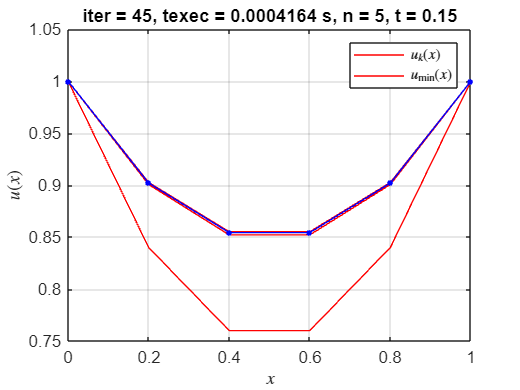

* Parabola:  Solución óptima encontrada en la iteración 9468, para n = 10, t = 0.001000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    9465    0.954115398067448    7.26623936296902e-07     0.750002555628375 
    9466    0.954115397539619    7.26202525838954e-07     0.750001543674738 
    9467    0.954115397012401    7.25781359098963e-07     0.750000532307083 
    9468    0.954115396485795    7.25360435970809e-07     0.749999521525068 



Valor mínimo de F(u) = F_min_aprox = 0.954115
|F_min_aprox - I_min_exacta| = 0.000491



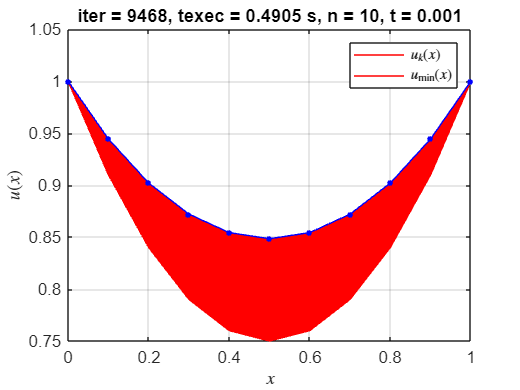

* Parabola:  Solución óptima encontrada en la iteración 945, para n = 10, t = 0.010000



     k           F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ___    _________________    ____________________    ___________________

    942    0.954115415302825     7.4025218995446e-06     0.750025998448866 
    943    0.954115409838982     7.3595925644851e-06     0.750015743128982 
    944    0.954115404438327    7.31691142930183e-06     0.750005547190848 
    945    0.954115399100132    7.27447706774072e-06      0.74999541029221 



Valor mínimo de F(u) = F_min_aprox = 0.954115
|F_min_aprox - I_min_exacta| = 0.000491



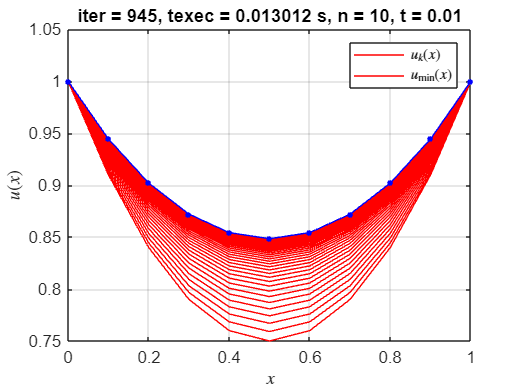

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 10, t = 0.150000



      k            F(u)          ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ________________    _________________    ___________________

     9997    1.14287899353169    0.258179589445983     1.98910249814077  
     9998    1.12904143822076    0.258179589445983     2.06033133545535  
     9999    1.14287899353169    0.258179589445983     1.98910249814077  
    10000    1.12904143822076    0.258179589445983     2.06033133545535  



Valor mínimo de F(u) = F_min_aprox = 1.142879
|F_min_aprox - I_min_exacta| = 0.189255



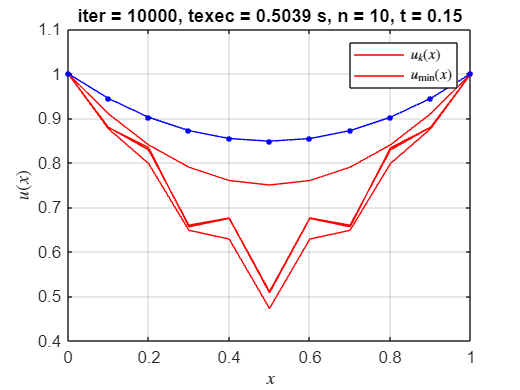

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 15, t = 0.001000



      k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    _____    _________________    ____________________    ___________________

     9997    0.953853807887855      2.971024018914e-06      0.75733722335413 
     9998    0.953853799062561    2.96988692332383e-06     0.757333844455302 
     9999     0.95385379024402    2.96875025621342e-06     0.757330466838387 
    10000    0.953853781432229    2.96761401721723e-06     0.757327090502908 



Valor mínimo de F(u) = F_min_aprox = 0.953854
|F_min_aprox - I_min_exacta| = 0.000230



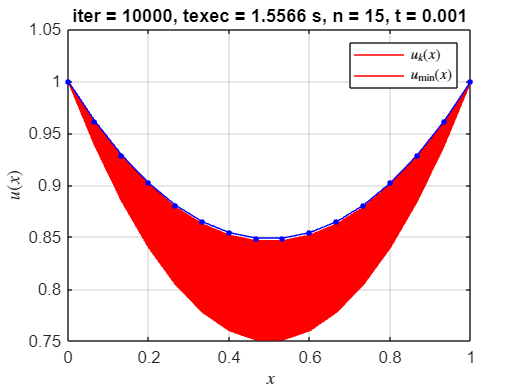

* Parabola:  Solución óptima encontrada en la iteración 1462, para n = 15, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1459    0.953842660049934    5.02039084302149e-06      0.75001596715527 
    1460    0.953842657534387    5.00092985511742e-06     0.750010236634153 
    1461    0.953842655038305    4.98154411350269e-06     0.750004528295484 
    1462    0.953842652561536    4.96223332882209e-06     0.749998842053738 



Valor mínimo de F(u) = F_min_aprox = 0.953843
|F_min_aprox - I_min_exacta| = 0.000218



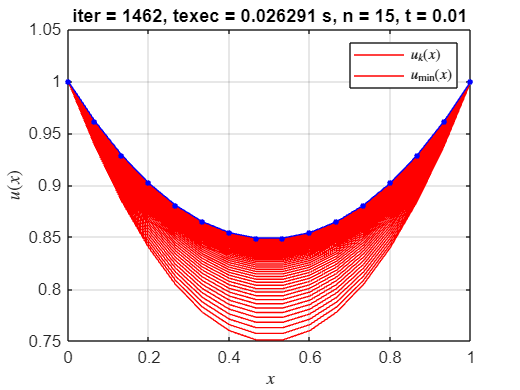

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 15, t = 0.150000



      k            F(u)          ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ________________    _________________    ___________________

     9997     1.1339877682629     0.17671740248141     1.56391140612515  
     9998    1.11567520491267    0.148900843725974      1.5142778048631  
     9999    1.10283550364693    0.134977435152866     1.54126897987104  
    10000    1.09742275522515    0.140175939198786     1.63771528731873  



Valor mínimo de F(u) = F_min_aprox = 1.103701
|F_min_aprox - I_min_exacta| = 0.150077



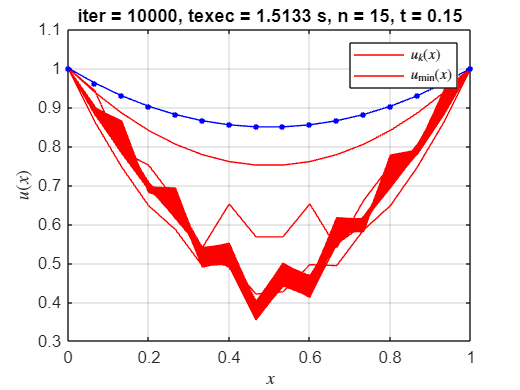

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 20, t = 0.001000



      k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    _____    _________________    ____________________    ___________________

     9997    0.953824059119328    6.62127215493992e-06     0.771432404584388 
     9998    0.953824015284224    6.61941718429705e-06     0.771425963959607 
     9999    0.953823971473678    6.61756271154967e-06     0.771419525094748 
    10000    0.953823927687676    6.61570873651179e-06     0.771413087989363 



Valor mínimo de F(u) = F_min_aprox = 0.953824
|F_min_aprox - I_min_exacta| = 0.000200



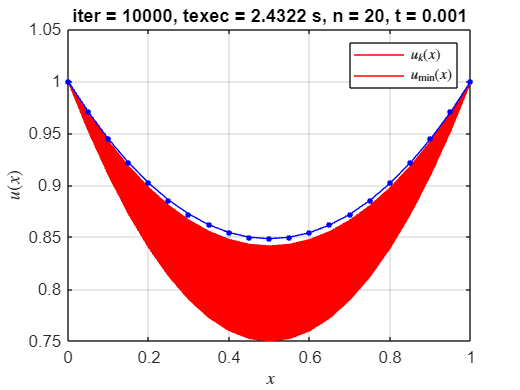

* Parabola:  Solución óptima encontrada en la iteración 1974, para n = 20, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    1971    0.953747154085823    4.02602392740328e-06     0.750008187639733 
    1972    0.953747152467294    4.01430817404522e-06     0.750004194025355 
    1973    0.953747150858173    4.00262643315315e-06     0.750000212016589 
    1974    0.953747149258402    3.99097860629167e-06     0.749996241579833 



Valor mínimo de F(u) = F_min_aprox = 0.953747
|F_min_aprox - I_min_exacta| = 0.000123



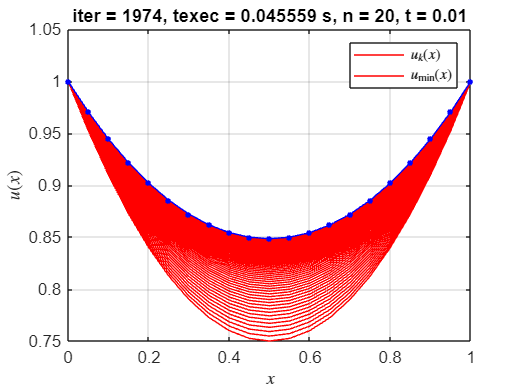

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 20, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.152079992293084     1.51607440516857  
     9998    -Inf    0.152079992293084     1.36826208292915  
     9999    -Inf    0.152079992293084     1.51607440516857  
    10000    -Inf    0.152079992293084     1.36826208292915  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



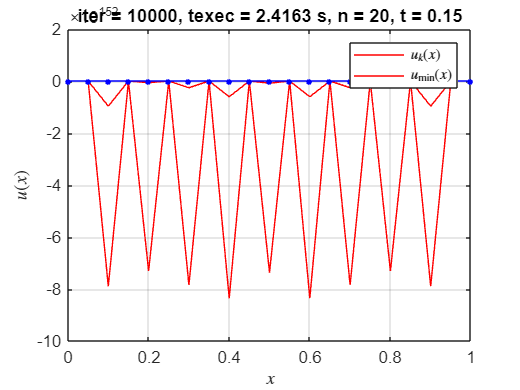

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 25, t = 0.001000



      k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    _____    _________________    ____________________    ___________________

     9997    0.953940156299898    1.02824633514641e-05      0.78853075337528 
     9998    0.953940050582327    1.02802302963823e-05      0.78852197043777 
     9999    0.953939944910667    1.02779976887598e-05     0.788513189319134 
    10000    0.953939839284902    1.02757655286293e-05     0.788504410019046 



Valor mínimo de F(u) = F_min_aprox = 0.953940
|F_min_aprox - I_min_exacta| = 0.000316



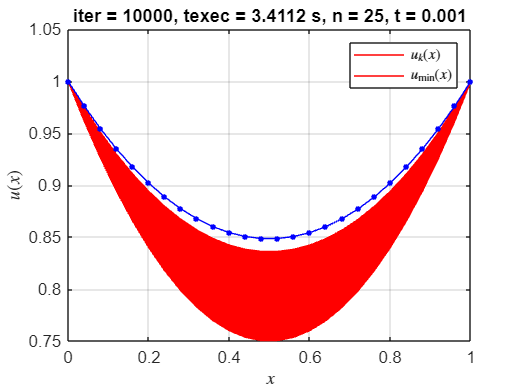

* Parabola:  Solución óptima encontrada en la iteración 2482, para n = 25, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    2479    0.953702942212147    3.47250175984622e-06     0.750006402258543 
    2480    0.953702941007724    3.46441428671515e-06     0.750003316030701 
    2481    0.953702939808905    3.45634560669174e-06     0.750000236981014 
    2482    0.953702938615664    3.44829567577363e-06     0.749997165092847 



Valor mínimo de F(u) = F_min_aprox = 0.953703
|F_min_aprox - I_min_exacta| = 0.000079



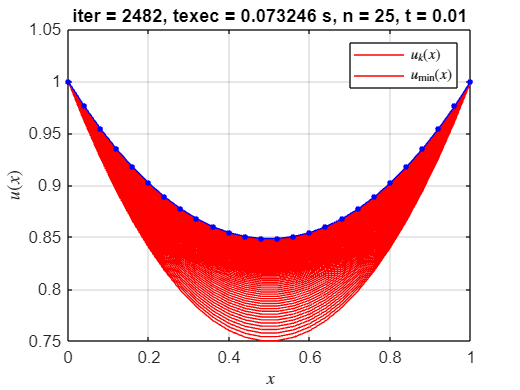

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 25, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.170947455651523     1.69832500326414  
     9998    -Inf    0.170947455651523     1.55163417912814  
     9999    -Inf    0.170947455651523     1.69832500326414  
    10000    -Inf    0.170947455651523     1.55163417912814  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



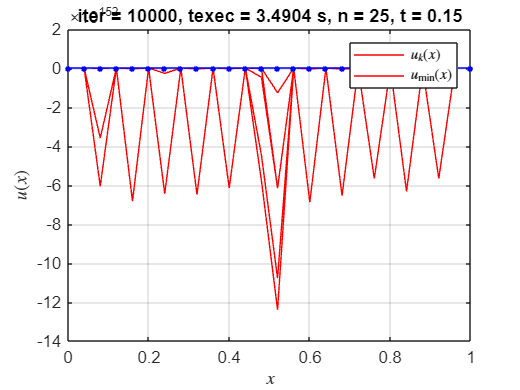

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 50, t = 0.001000



      k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    _____    _________________    ____________________    ___________________

     9997    0.955655430905686    2.01432318238515e-05     0.862282127093569 
     9998    0.955655025174723    2.01413627060786e-05     0.862271080972458 
     9999    0.955654619519053    2.01394937124713e-05     0.862260035699707 
    10000    0.955654213938665     2.0137624842932e-05     0.862248991275298 



Valor mínimo de F(u) = F_min_aprox = 0.955654
|F_min_aprox - I_min_exacta| = 0.002030



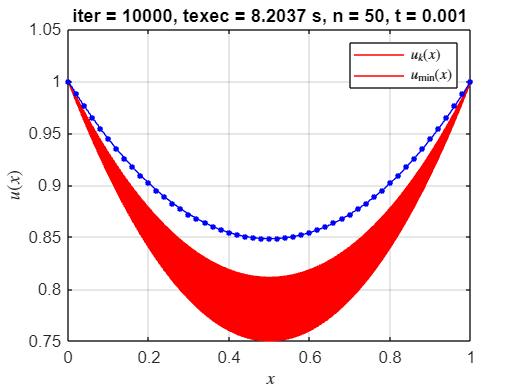

* Parabola:  Solución óptima encontrada en la iteración 5004, para n = 50, t = 0.010000



     k            F(u)            ||u_{k+1} - u_k||      ||grad_F(u_{k+1})||
    ____    _________________    ____________________    ___________________

    5001    0.953643986123465    2.33438763646224e-06     0.750004381846178 
    5002    0.953643985578846    2.33166767859427e-06     0.750002910868014 
    5003    0.953643985035496    2.32895088315059e-06     0.750001441601482 
    5004     0.95364398449341    2.32623724624674e-06     0.749999974044598 



Valor mínimo de F(u) = F_min_aprox = 0.953644
|F_min_aprox - I_min_exacta| = 0.000020



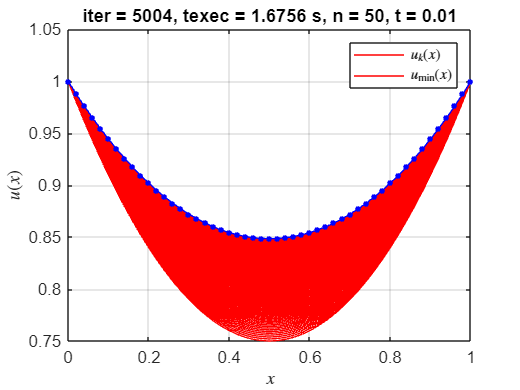

* Parabola:  Solución óptima encontrada en la iteración 10000, para n = 50, t = 0.150000



      k      F(u)    ||u_{k+1} - u_k||    ||grad_F(u_{k+1})||
    _____    ____    _________________    ___________________

     9997    -Inf    0.186786338656144     1.86587795664023  
     9998    -Inf    0.186786338656144     1.72370729187847  
     9999    -Inf    0.186786338656144     1.86587795664023  
    10000    -Inf    0.186786338656144     1.72370729187847  



Valor mínimo de F(u) = F_min_aprox = -Inf
|F_min_aprox - I_min_exacta| = Inf



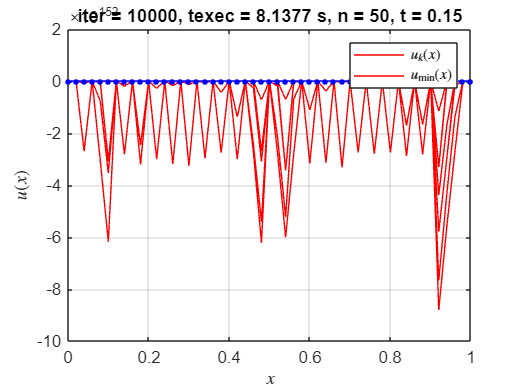

% Insertar código para aproximación de parábola
clc; clear; close all;
format longg;
% % parámetros...
n_vector = [5, 10, 15, 20, 25, 50];
t_vector = [0.001, 0.01,0.15];


delta_1 = 1e-5;
delta_2 = 0.75;
max_k = 10000;

% Estructura para guardar resultados
resultados = struct();

% % Crear carpeta para guardar resultados
output_folder = 'resultados_pdf';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

% % salidas...
l = length(n_vector);
tiledlayout(1, l);
iter=0;
tic
for n_idx = 1:length(n_vector)
    for t_idx = 1:length(t_vector)
        % Definir parámetros actuales
        n = n_vector(n_idx);
        t = t_vector(t_idx);    
        iter=iter+1;
        [tabla_iteraciones, u_min_aprox, u_hist, k, texec] = metodo_gradiente_paso_fijo_para(n, t, delta_1, delta_2, max_k);
        % calculo valores exactos...
        x = 0:1/n:1;
        a = 0.848338;
        u_min_exacta = a*cosh((x-1/2)/a); % catenaria exacta
        I_min_exacta = (a/2)*(1 + a*sinh(1/a)); % se ha obviado el 2*pi
        fprintf('* Parabola:  Solución óptima encontrada en la iteración %d, para n = %d, t = %f\n\n', k, n, t);
        % tabulo...
        disp(array2table(tabla_iteraciones(end-3:end,:), 'VariableNames', {'k', 'F(u)', '||u_{k+1} - u_k||', '||grad_F(u_{k+1})||'}));
        F_min_aprox = F(u_min_aprox);
        
        % Guardar resultados en la estructura
        resultados(iter).n = n;
        resultados(iter).t = t;
        resultados(iter).tabla_iteraciones = tabla_iteraciones;
        resultados(iter).u_min_aprox = u_min_aprox;
        resultados(iter).u_hist = u_hist;
        resultados(iter).k = k;
        resultados(iter).texec = texec;
        resultados(iter).u_min_exacta = u_min_exacta;
        resultados(iter).I_min_exacta = I_min_exacta;
        resultados(iter).F_min_aprox = F_min_aprox;
        resultados(iter).error = abs(F_min_aprox - I_min_exacta);

        fprintf('Valor mínimo de F(u) = F_min_aprox = %f\n|F_min_aprox - I_min_exacta| = %f\n\n', F_min_aprox, abs(F_min_aprox - I_min_exacta));
        % grafico...
        figure(iter);
        plot(x, u_hist(1:20:end,:)', 'r', ...          % Color rojo para u_hist
             x, u_min_aprox', 'r', ...                % Color rojo para u_min_aprox
             x, u_min_exacta, '.-b', 'MarkerSize', 10); % Color azul para u_min_exacta con estilo y tamaño del marcador      
        xlabel('$$x$$', 'Interpreter', 'latex'); 
        ylabel('$$u(x)$$', 'Interpreter', 'latex');
        legend('$$u_{k}(x)$$', '$$u_{\min}(x)$$', 'Interpreter', 'latex');
        title(['iter = ', num2str(k), ', texec = ', num2str(texec), ' s, n = ', num2str(n), ', t = ', num2str(t)]);
        grid on;

        % Guardar la figura
        % saveas(gcf, fullfile(output_folder, sprintf('final_n%d_t%.3f.pdf', n, t)));       
    end
end


elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 8.4535 segundos en ejecutarse.


save('resultados_t_fijo.mat','resultados');

Ambos métodos de paso fijo, tanto si se inicia la solución del problema con la parábola x^2-x+1 como si se toma la constante igual a 1 como punto de inicio, consiguen converger a la solución esperada. De las gráficas y resultados obtenidos se debe comentar la sensibilidad a los parámetros t y n, es decir, el salto por paso y la discretización que se ha seleccionado para resolver el problema.

Las gráficas muestran las iteraciones progresivas, en rojo, converginedo a la solución analítica, en azul. Cuando los parámetros t y n no se eligen de manera a decuada; el resultado es la imposibilidad de converger a la solución buscada. Por otra parte, considerar que tanto si se inicia la ejecución con una curva con valores generalmente mayores que la solución analítica (como para la constante 1) o si se inicia con valores inferiores como en el caso de la parábola, el método de gradiente empleado que minimza la superficie de revolución, dirige la solución a la catenaria anteriormente discutida.

De los resultados obtenidos se puede comprobar que las mejores soluciones son obtendias para t=0.01; o en su defecto para t pequeños, esto permite suavizar la obtención de la nueva aproximación de u. Aunque puede incurrir en ralentización del cálculo y aumento del número de iteraciones, parece ser la aproximación más robusta para converger a la solución analítica.

## **Método de paso variable**

### Gradiente con paso variable para N = 50

SUPERFICIE MÍNIMA DE REVOLUCIÓN - (DICO)
PROGRESO DE OPTIMIZACIÓN - N = 50 PUNTOS
Iteración    Área            t               Norma Gradiente
-----------------------------------------------------------------
2970         0.937915        0.011960        0.924460       
2980         0.937915        0.011960        0.924559       
2990         0.937915        0.011960        0.924441       
3000         0.937918        0.011967        0.924534       
3010         0.937917        0.011960        0.924829       
3020         0.937917        0.011960        0.924910       
3030         0.937919        0.011967        0.924799       
3040         0.937920        0.011967        0.924909       
3050         0.937919        0.011960        0.925227       
3060         0.937920        0.011967        0.924938       
-------------------------------------------------

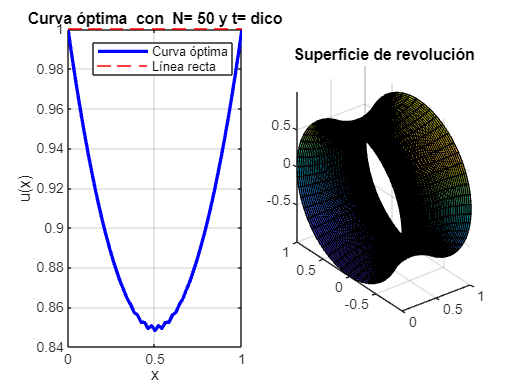

clear, clc, close all;
digits(32)
format shortG
tic;
n = 50;           % número de puntos
max_iter = 10000;   % máximo de iteraciones
tol = 1e-5; % tolerancia máxima
integral_method = 'trapezium';
t_opt_metod = 'dico';
verbose = true;
make_plot = true;
[u_opt, min_area, alpha_opt] = min_rev_surface(n, max_iter, tol,integral_method, t_opt_metod, verbose, make_plot);

elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 0.4352 segundos en ejecutarse.


### Gradiente con paso variable para distintos puntos

clear, clc, close all;
digits(32)
format shortG

% ********************************************************************%
% ******************* BENCHMARK **************************************%
%% Con tolerancia constante y 32 digitos de precisión
tic;
max_iter = 10000;   % máximo de iteraciones
tol = 1e-5; % tolerancia máxima
n_values = [5, 10, 15, 20, 25, 50, 75]; % rectas inexactas no tolera n < 15
integral_methods = {'trapezium'};
t_opt_methods = {'fibo', 'dico'};

results = table('Size', [numel(n_values)*numel(integral_methods)*numel(t_opt_methods), 6], ...
    'VariableTypes', {'double', 'double', 'double', 'double', 'double', 'string'}, ...
    'VariableNames', {'n','iters','min_area', 't_opt', 'mean_norm_grad', 't_opt_method'});

row = 1;
for n = n_values
    for integral_method = integral_methods
        for t_opt_method = t_opt_methods
            [u_opt, iters, min_area, t_opt, mean_error] = min_rev_surface(n, max_iter, tol, integral_method{1}, t_opt_method{1});
            results.n(row) = n;
            results.iters(row) = iters;
            results.min_area(row) = min_area;
            results.t_opt(row) = t_opt;
            results.mean_norm_grad(row) = mean_error;
            results.t_opt_method(row) = string(t_opt_method{1});
            row = row + 1;
        end
    end
end

disp(results)

    n     iters    min_area      t_opt      mean_norm_grad    t_opt_method
    __    _____    ________    _________    ______________    ____________

     5      69     0.82285       0.13363       0.87646           "fibo"   
     5      85     0.82273       0.13971       0.86777           "dico"   
    10      66     0.88197      0.070554        0.8939           "fibo"   
    10      47      0.8823      0.057209       0.93436           "dico"   
    15     103     0.90423      0.041098       0.92384           "fibo"   
    15     163     0.90423      0.041081       0.92384           "dico"   
    20     505     0.91582      0.030445        0.9249           "fibo"   
    20     553     0.91582      0.030446       0.92507           "dico"   
    25     807     0.92301      0.024345     

elapsedTime = toc;
% Muestra el tiempo transcurrido
fprintf('El algoritmo tardó %.4f segundos en ejecutarse.\n', elapsedTime);

El algoritmo tardó 0.0669 segundos en ejecutarse.


save('resultados_t_variable.mat', "results")

## **Análisis y resultados**

### **Área minima y el número de puntos N**

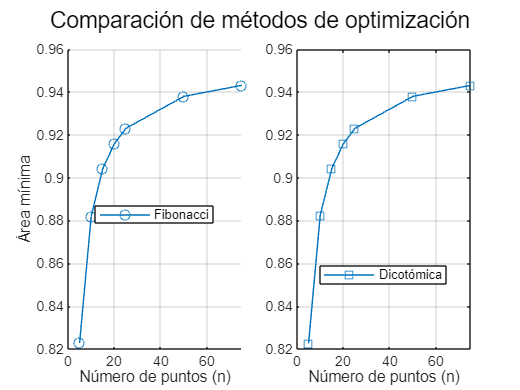

figure;

% Crear subplots
subplot(1, 2, 1);
hold on;

% Graficar min_area vs n para el método 'fibo'
plot(results.n(strcmp(results.t_opt_method, 'fibo')), ...
     results.min_area(strcmp(results.t_opt_method, 'fibo')), ...
     '-o', 'DisplayName', 'Fibonacci');
xlabel('Número de puntos (n)');
ylabel('Área mínima');
% Leyendas
legend('Location', 'best');
grid on;

subplot(1, 2, 2);
% Graficar min_area vs n para el método 'dico'
plot(results.n(strcmp(results.t_opt_method, 'dico')), ...
     results.min_area(strcmp(results.t_opt_method, 'dico')), ...
     '-s', 'DisplayName', 'Dicotómica');

% Etiquetas y título comunes
sgtitle('Comparación de métodos de optimización'); % Título general
xlabel('Número de puntos (n)');
% Leyendas
legend('Location', 'best');
grid on;

hold off;

Esta figura anterior se muestran dos gráficos que comparan los métodos de optimización de Fibonacci y búsqueda dicotómica. Ambos gráficos muestran un comportamiento de convergencia similar a medida que aumenta el número de puntos (N). El mínimo de superficie se acerca a aproximadamente 0,94 cuando n alcanza los 60 puntos. 

Ambos métodos muestran una rápida convergencia inicial hasta aproximadamente n = 20, después de lo cual la mejora se vuelve más gradual. 

El método dicotómico parece tener un comportamiento de progresión ligeramente más suave en comparación con el método de Fibonacci.

### Cáculo del Área mínima y el método de búsqueda de t óptimo

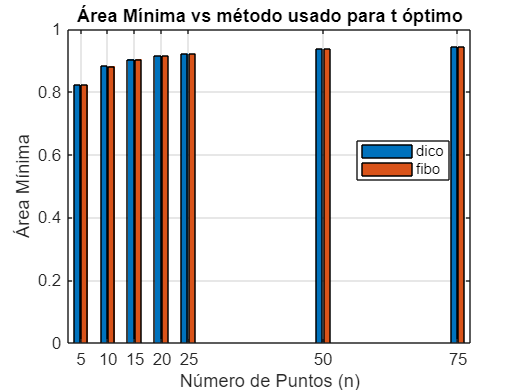

% Valores únicos
n_values = unique(results.n);
t_opt_methods = unique(results.t_opt_method);

% Preasignación de matriz con n y método de t óptimo
min_area_matrix = zeros(length(n_values), length(t_opt_methods));

% Rellenar la matriz con datos min_area
for i = 1:length(n_values)
    for j = 1:length(t_opt_methods)
        mask = results.n == n_values(i) & results.t_opt_method == t_opt_methods(j);
        min_area_matrix(i, j) = results.min_area(mask);
    end
end

figure;
bar(n_values, min_area_matrix, 'grouped');
xlabel('Número de Puntos (n)');
ylabel('Área Mínima');
title('Área Mínima vs método usado para t óptimo');
legend(t_opt_methods, 'Location', 'best');
grid on;

En el gráfico de barras se compara el área mínima obtenida por los dos métodos (Búsqueda dicotómica y Fibonacci) a diferentes números de puntos (5, 10, 15, 20, 25 y 50). Los resultados muestran que ambos métodos logran resultados muy similares en todos los valores de puntos y además que el área mínima aumenta con el número de puntos,estabilizándose alrededor de 0,93-0,94

No se evidencia una diferencia significativa entre el rendimiento de los dos métodos en términos de área mínima final obtenida.

### Estudio del perfil del gradiente

#### *Para t fijo*

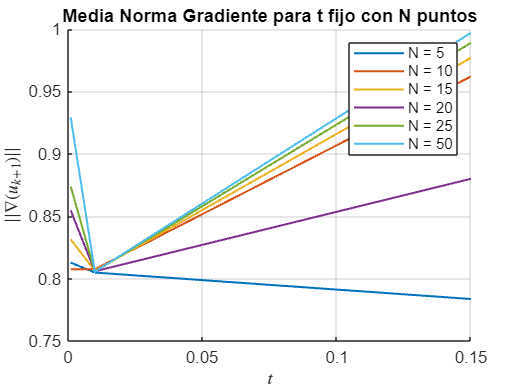

r = load("resultados_t_fijo.mat");

figure;
hold on

n_values = unique([r.resultados.n]);
t_values = unique([r.resultados.t]);

for i = 1:length(n_values)
    current_n = n_values(i);
    idx = find([r.resultados.n] == current_n);
    mean_errors = zeros(size(t_values));
    for j = 1:length(t_values) 
        idx_nt = find([r.resultados.n] == current_n & [r.resultados.t] == t_values(j));

        error_data = r.resultados(idx_nt).tabla_iteraciones(:,4);
        error_data = error_data(error_data < 1);
        if ~isempty(idx_nt)
            mean_errors(j) = mean(error_data);
        end
    end
    
    plot(t_values, mean_errors, ...
         'LineWidth', 1.2, ...
         'DisplayName', sprintf('N = %d', current_n));
end

xlabel('$$t$$', 'Interpreter', 'latex');
ylabel('$$||\nabla(u_{k+1})||$$', 'Interpreter', 'latex');
title('Media Norma Gradiente para t fijo con N puntos');
grid on;
legend('show');

hold off

Este gráfico muestra la evolución de la norma de gradiente para diferentes números de puntos (Desde 5 hasta 50) en comparación con un paso de tamaño fijo t. Todas las curvas muestran un aumento inicial en la norma del gradiente.Además, los valores de N más bajos (especialmente N = 5) muestran un comportamiento más estable, pero con valores de N más altos muestran disminuciones más notables en la norma del gradiente para distintos valores de t

Las curvas divergen considerablemente después de t≈0.05, lo que sugiere que la elección del tamaño del paso se vuelve más crítica con más puntos.

#### Para t variable

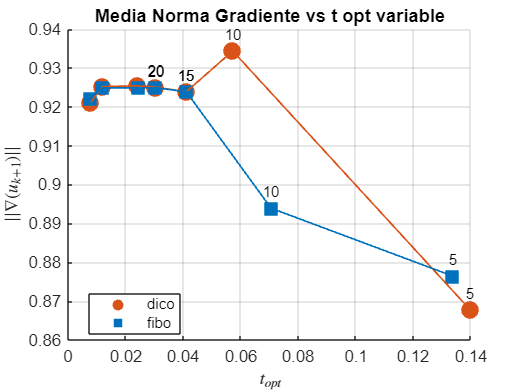


r_variable = load("resultados_t_variable.mat");
t_opt = r_variable.results.t_opt;
mean_norm_grad = r_variable.results.mean_norm_grad;
n = r_variable.results.n;
t_opt_method = r_variable.results.t_opt_method;

unique_methods = unique(t_opt_method);
shapes = {'o', 's'};
colors = [0.8500 0.3250 0.0980; 0.0000 0.4470 0.7410]; % Paleta mejorada (rojo y azul)

figure;
hold on;

for i = 1:length(unique_methods)
    method_mask = strcmp(t_opt_method, unique_methods{i});
    scatter(t_opt(method_mask), mean_norm_grad(method_mask), 100, ...
        'Marker', shapes{i}, 'MarkerEdgeColor', colors(i, :), ...
        'MarkerFaceColor', colors(i, :), 'DisplayName', unique_methods{i});

    % Añadir etiquetas de n sobre cada punto
    for j = find(method_mask, 4)'
        text(t_opt(j), mean_norm_grad(j) + 0.002, sprintf('%d', n(j)), ...
             'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', ...
             'FontSize', 9, 'Color', 'k');
    end
end

% Línea de tendencia por método
for i = 1:length(unique_methods)
    method_mask = strcmp(t_opt_method, unique_methods{i});
    plot(t_opt(method_mask), mean_norm_grad(method_mask), ...
        'Color', colors(i, :), 'LineStyle', '-', 'LineWidth', 1, 'HandleVisibility', 'off');
end

xlabel('$$t_{opt}$$', 'Interpreter', 'latex');
ylabel('$$||\nabla(u_{k+1})||$$', 'Interpreter', 'latex');
title('Media Norma Gradiente vs t opt variable');
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 10);
hold off;

El gráfico anterior compara los valores t óptimos para los dos métodos, y, de este se desprende que ambos métodos convergen a valores finales similares alrededor de t = 0,15. El método dicotómico (dico) muestra un pico alrededor de t = 0,05. También, el método Fibonacci (fibo) muestra una disminución más gradual. Además, se evidencia que ambos métodos funcionan de manera similar para una mayor cantidad de puntos (50, 25, 15) pero con valores de t pequeños.

## CONCLUSIONES

La implementación de métodos de descenso de gradiente para encontrar superficies mínimas de revolución demuestra de manera exitosa la aplicación práctica de la optimización multivariada sin restricciones. A través de una exploración sistemática de tamaños de paso fijos y variables, hemos establecido una relación entre los fundamentos teóricos y su implementación computacional. La comparación entre diferentes funciones iniciales y métodos de selección del tamaño de paso proporcionó información valiosa sobre la dinámica de optimización en el ejercicio en cuestión. 

Además, esta actividad conecta efectivamente los conceptos introducidos en el tema 2 (búsqueda unidimensional) con desafíos computacionales más complejos, destacando la importancia de una selección de parámetros adecuada y una estrategia de optimización para lograr la convergencia. 

La elección del número de puntos (N) tiene un impacto significativo en el comportamiento de optimización, y los valores de N más altos generalmente conducen a soluciones más estables pero más intensivas desde el punto de vista computacional. La selección del tamaño de paso óptimo (t) parece ser más crítica para valores intermedios, mientras que ambos métodos convergen a resultados finales similares.

Finalmente, está práctica se centró particularmente en el papel de los tamaños de paso adaptativos en la mejora del rendimiento de la optimización, al tiempo que evidencian los requisitos computacionales inherentes a este tipo de problemas.

## **REFERENCIAS**

- Bonnans, J. F., Gilbert, J. C., Lemaréchal, C., & Sagastizábal, C. A. (2021). Numerical optimization: Theoretical and practical aspects. Springer.

- Boyd, S., & Vandenberghe, L. (2020). Convex optimization. Cambridge University Press.

- Nocedal, J., & Wright, S. J. (2022). Numerical optimization (3rd ed.). Springer Science.

- Sun, W., & Yuan, Y. X. (2021). Optimization theory and methods: Nonlinear programming. Springer.

## ANEXOS

### Anexo I: Método Gradiente Paso fijo

#### Con aproximacióna a una recta u(x)  = 1

function [tabla_iteraciones, u, u_hist, k, texec] = metodo_gradiente_paso_fijo(n, t, delta_1, delta_2, max_k)
    k = 0; % índice de iteración
    error_1 = delta_1 + 1; % error ||u_{k+1} - u_k||
    error_2 = delta_2 + 1; % error ||grad_f(u_{k+1})||
    u = ones(n+1, 1); % vector de inicio
    u_hist = u'; % guarda historial de iteraciones
    tabla_iteraciones = [];
    tic;
    while (error_1 > delta_1 || error_2 > delta_2) && k < max_k
    k = k + 1;
    u_nuevo = u - t * grad_F(u);
    u_nuevo(1) = 1; u_nuevo(n+1) = 1; % exijo las condiciones de contorno!!!
    error_1 = norm(u_nuevo - u);
    error_2 = norm(grad_F(u_nuevo));
    tabla_iteraciones = [tabla_iteraciones; k, F(u), error_1, error_2];
    u = u_nuevo;
    u_hist = [u_hist; u'];
    end
    texec = toc;
end

#### Con aproximacióna a una parábola u(x) = x^2-x+1;

function [tabla_iteraciones, u, u_hist_para, k, texec] = metodo_gradiente_paso_fijo_para(n, t, delta_1, delta_2, max_k)
    k = 0; % índice de iteración
    error_1 = delta_1 + 1; % error ||u_{k+1} - u_k||
    error_2 = delta_2 + 1; % error ||grad_f(u_{k+1})||
    
   
    x_i = 0:1/n:1;
    
    u = ones(n+1,1);% vector de inicio
    for i=2:n
        
        u(i) = x_i(i)^2-x_i(i)+1;
    end
    u_hist_para = u'; % guarda historial de iteraciones
    tabla_iteraciones = [];
    tic;
    while (error_1 > delta_1 || error_2 > delta_2) && k < max_k
    k = k + 1;
    u_nuevo = u - t * grad_F(u);

    u_nuevo(1) = 1; u_nuevo(n+1) = 1; % exijo las condiciones de contorno!!!
    error_1 = norm(u_nuevo - u);
    error_2 = norm(grad_F(u_nuevo));
    tabla_iteraciones = [tabla_iteraciones; k, F(u), error_1, error_2];
    u = u_nuevo;

    u_hist_para = [u_hist_para; u'];
    end
    texec = toc;
end


### Anexo II: Función Integral

function integral = F(u)
    n = length(u) - 1;
    integral = 0;
    for j = 1:n
    integral = integral + (u(j+1)+u(j)) * sqrt(1 + (n*(u(j+1)-u(j)))^2);
    end
    integral = integral/(2*n);
end


### Anexo III: Función gradiente

function gradiente = grad_F(u)
    l = length(u);
    n = l - 1;
    c = 1/(2*n);
    gradiente(1) = (c - u(1)*n*(u(2)-u(1))) / sqrt(1 + (n*(u(2)-u(1)))^2);
    for j = 2:n
    gradiente(j) = (c + u(j)*n*(u(j)-u(j-1))) / sqrt(1 + (n*(u(j)-u(j-1)))^2) + ...
    (c - u(j)*n*(u(j+1)-u(j))) / sqrt(1 + (n*(u(j+1)-u(j)))^2);
    end
    gradiente(l) = (c + u(l)*n*(u(l)-u(l-1))) / sqrt(1 + (n*(u(l)-u(l-1)))^2);
    gradiente = gradiente';
end



### Anexo III: Método Gradiente Paso variable

function [u_optimal, n_iter, min_area, alpha_opt, mean_norm_grad] = min_rev_surface(n, max_iter, tol, integral_method, t_opt_method, verbose, make_plot)
    % Marcando parámetros de entrada
    if nargin < 1, n = 100; end        % número de puntos
    if nargin < 2, max_iter = 1000; end % máximo de iteraciones
    if nargin < 3, tol = 1e-4; end % tolerancia por defecto
    if nargin < 4, integral_method = 'trapezium'; end % Método del trapecio por defecto
    if nargin < 5, t_opt_method = 'fibo';  end % método para encontra t óptimo
    if nargin < 6, verbose = false;  end % verbose igual true mostrará las últimas 10 iteraciones
    if nargin < 7, make_plot = false;  end % método para encontra t óptimo

    % Inicialización
    x = linspace(0, 1, n+1);
    u = ones(1, n+1);  % línea recta para y=1
    iter = 0;
    % Se guardan las últimas 10 iteraciones
    last_areas = zeros(1, 10);
    last_alphas = zeros(1, 10);
    last_norms = zeros(1, 10);
    last_iters = zeros(1, 10);

    % Método de optimización sin restricciones (método del gradiente con t variable)
    if strcmp(integral_method, 'trapezium')
        while iter < max_iter
                grad = trapezium_gradient(u, n);

                % establecemos función de línea para búsqueda de alpha
                f = @(alpha) trapezium(u - alpha .* grad, n); 
                df = @(alpha) -sum(grad .* grad); %Sumatoria del vector gradiente  

                % Llamando a la función Fibonacci o Rectas Inexactas para búsqueda de alpha (t) óptimo
                if strcmp(t_opt_method, 'fibo')
                    [alpha, ~] = fibo(f, df, 0, 1, tol);
                elseif strcmp(t_opt_method, 'dico')
                    [alpha, ~] = budi(f, df, 0, 1, tol);
                end
                % Actualizar u a excepción de los puntos u(a) y u(b) que deben ser 1
                u_new = u - alpha .* grad;
                % Criterio de parada
                if iter > 1 && abs(norm(u_new(2:end-1)) - norm(u(2:end-1))) < tol
                    break;
                end

                u(2:end-1) = u_new(2:end-1);
                iter  = iter+1;
                area = trapezium(u, n);

                if mod(iter, 10) == 0
                last_areas = [last_areas(2:end), area];
                last_alphas = [last_alphas(2:end), alpha];
                last_norms = [last_norms(2:end), norm(grad)];
                last_iters = [last_iters(2:end), iter];
                end
        end
        if verbose == true
            fprintf('\n%s\n', '=================================================================');
            fprintf('SUPERFICIE MÍNIMA DE REVOLUCIÓN - (%s)\n', upper(t_opt_method));
            fprintf('PROGRESO DE OPTIMIZACIÓN - N = %d PUNTOS\n', n);
            fprintf('%s\n', '=================================================================');
            fprintf('%-12s %-15s %-15s %-15s\n', 'Iteración', 'Área', 't', 'Norma Gradiente');
            fprintf('%s\n', '-----------------------------------------------------------------');
            
    
            start_idx = find(last_iters > 0, 1);
            if isempty(start_idx), start_idx = 1; end
            
            
            for i = start_idx:10
                if last_iters(i) > 0  % Only print if there was an actual iteration
                    fprintf('%-12d %-15.6f %-15.6f %-15.6f\n', ...
                        last_iters(i), last_areas(i), last_alphas(i), last_norms(i));
                end
            end
            fprintf('%s\n', '-----------------------------------------------------------------');
        end
        u_optimal = u;
        min_area = trapezium(u_optimal, n);
        alpha_opt = alpha;
        mean_norm_grad = mean(norm(grad));
        n_iter = iter;
        % Graficamos
    if make_plot == true
        plot_result(x, u_optimal, t_opt_method);
    end
    end
end
% Gradiente
function grad = trapezium_gradient(u, n)
    grad = zeros(1, n+1);
    grad(1) = (1/(2*n)) * (sqrt(1 + n^2*(u(2) - u(1))^2) - ... 
               (n^2*(u(2) - u(1))*(u(2) + u(1)))/sqrt(1 + n^2*(u(2) - u(1))^2));

    % k = 1,2,...,n-1
    for k = 2:n
        grad(k) = (1/(2*n)) * (sqrt(1 + n^2*(u(k) - u(k-1))^2) + ...
                  (n^2*(u(k) - u(k-1))*(u(k) + u(k-1)))/sqrt(1 + n^2*(u(k) - u(k-1))^2) + ...
                  sqrt(1 + n^2*(u(k+1) - u(k))^2) - ...
                  (n^2*(u(k+1) - u(k))*(u(k+1) + u(k)))/sqrt(1 + n^2*(u(k+1) - u(k))^2));
    end

    % k = n
    grad(n+1) = (1/(2*n)) * (sqrt(1 + n^2*(u(n+1) - u(n))^2) + ... 
                (n^2*(u(n+1) - u(n))*(u(n+1) + u(n)))/sqrt(1 + n^2*(u(n+1) - u(n))^2));
end

% Área bajo la curva método del trapezio
function area = trapezium(u, n)
    area = 0;
    for j = 1:n
        Tj = (u(j) + u(j+1)) * sqrt(1 + (n+1)^2 * (u(j+1) - u(j))^2) / (2*(n+1));
        area = area + Tj;
    end
end

function plot_result(x, u, t_opt_method)
    figure;
    subplot(1,2,1)
    plot(x, u, 'b-', 'LineWidth', 2);
    hold on;
    plot([0,1], [1,1], 'r--');  % Línea recta original
    grid on;
    title(['Curva óptima  con  N= ' num2str(length(x) - 1) ' y t= ' t_opt_method]); 
    xlabel('x');
    ylabel('u(x)');
    legend('Curva óptima', 'Línea recta');
    % Graficar superficie de revolución
    subplot(1,2,2)
    theta = linspace(0, 2*pi, 50);
    [X, T] = meshgrid(x, theta);
    U = repmat(u, length(theta), 1);
    Y = U .* cos(T);
    Z = U .* sin(T);
    surf(X, Y, Z);
    title('Superficie de revolución');
    axis equal;
    grid on;

end


### Anexo IV: Métodos de búsqueda para t óptimo

#### Fibonacci

function [x_min,f_min,k, prec, lapse] = fibo(fun,dfun,a,b,tol)
    I0 = [a, b];
    % F0 = fun(I0);
    F0 = [fun(I0(1)), fun(I0(2))];
    w1 = I0(2) - I0(1);
    max_iter = 50;
    epsilon = 1e-6;
    
    tic;
    % Fibonacci serie implementation
    F = zeros(max_iter, 1);
    F(1) = 1; F(2) = 1; n = 2;

    while w1 > tol*F(n)
        n = n+1;
        F(n) = F(n-1) + F(n-2);
    
    end

    % Fibonacci search algorithm
    w = w1*(F(n-2)/F(n-1));
    xa = I0(2) - w; 
    xb = I0(1) + w;
    fa = fun(xa); 
    fb = fun(xb);
    k = 0;
    
    for n=2:n-2
        w = w*(F(n-k-1)/F(n-k));
        if fa > fb
            I0(1) = xa; F0(1) = fa; xa = xb; fa = fb; xb = xa + w; fb = fun(xb);
        else
            I0(2) = xb; F0(2) = fb; xb = xa; fb = fa; xa = xb - w; fa = fun(xa); 
        end
    
        width_interval = abs(I0(2) - I0(1));
    
        if width_interval < tol
            break;
        end
    
    end
    x_min = (I0(2) + I0(1))/2;
    f_min = fun(x_min);
    k = n;
    prec = abs(dfun(x_min));
    lapse = toc;
    lapse = vpa(lapse);
end

#### Búsqueda Dicotómica

function [x_min,f_min,k_opt,prec, lapse] = budi(fun,dfun, a, b, tol)
epsilon = 1e-6;
max_iter = 50;
k = 0;

tic;
x1 = (a+b)/2;
xa = x1-(epsilon/2);
xb = x1 + (epsilon/2);

while abs(b-a) >= tol && k < max_iter

if fun(xa) <= fun(xb)
    b=xb; a=a;
elseif fun(xa) > fun(xb)
    a=xa; b=b;
end

x1 = (a + b) /2;
xa = x1-(epsilon/2);
xb = x1 + (epsilon/2);
fl = fun(a);
fr=fun(b);

k = k+1;

end
x_min = (a+b)/2;
f_min = fun(x_min);
k_opt = k;
prec = abs(dfun(x_min));
lapse = toc;
lapse = vpa(lapse);
end